PRACTICA 3

3.11 y 3.12) DTFT de la respuesta de un sistema

n=0:20

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


x=3*cos(0.5*pi.*n+(pi/3)); %no la necesito, es lo mismo que la funcion y
nh=-11:11

nh =    -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11


h=0.5.^abs(nh).*cos(0.1*pi.*nh);
H=DTFT(h,nh,[0.5*pi,-0.5*pi,0.3*pi,-0.3*pi])

H =    0.6394 - 0.0000i   0.6394 + 0.0000i   1.2492 - 0.0000i   1.2492 + 0.0000i


y=((0.75+j*1.3)*exp(j*0.5*pi.*n)*H(1)+(0.75-1.3*j)*exp(-0.5*j*pi.*n)*H(2)-j*exp(0.3*j*pi.*n)*H(3)+j*exp(-0.3*j*pi.*n))*H(4)

y =    1.1981 - 0.3113i   0.1963 - 0.1830i   1.4740 + 0.0962i   2.9450 + 0.2961i  -0.4534 + 0.2518i  -4.8864 + 0.0000i  -2.8496 - 0.2518i   2.9450 - 0.2961i   3.8703 - 0.0962i   0.1963 + 0.1830i  -1.1981 + 0.3113i  -0.1963 + 0.1830i  -1.4740 - 0.0962i  -2.9450 - 0.2961i   0.4534 - 0.2518i   4.8864 - 0.0000i   2.8496 + 0.2518i  -2.9450 + 0.2961i  -3.8703 + 0.0962i  -0.1963 - 0.1830i   1.1981 - 0.3113i


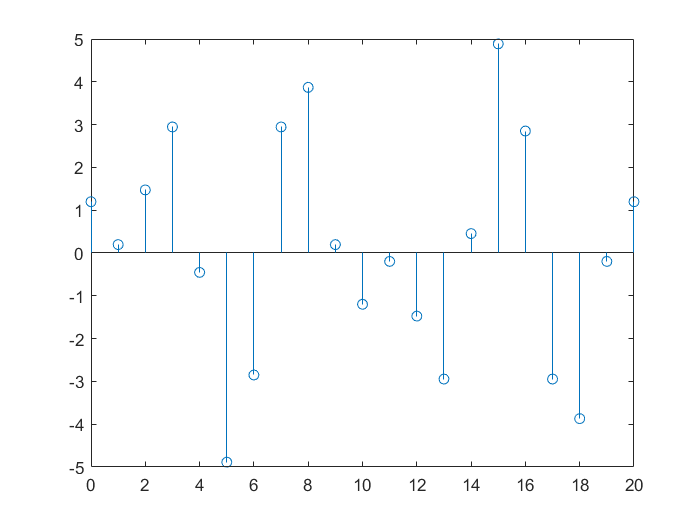

%OJO hay que multiplicar por cada posicion de frecuencia, H(1) es la frec 0.5*pi
%OJO me quedo con la parte real de y
stem(n,real(y))

5.1.d Calcula los coeficientes de la DFS

x4=[1j,1j,-1j,-1j];
X4=fft(x4)

X4 =    0.0000 + 0.0000i   2.0000 + 2.0000i   0.0000 + 0.0000i  -2.0000 + 2.0000i


5.2.c Calcula la secuencia periodica 

X3=[1,2,3,4,5];
x3=ifft(X3)

x3 =    3.0000 + 0.0000i  -0.5000 - 0.6882i  -0.5000 - 0.1625i  -0.5000 + 0.1625i  -0.5000 + 0.6882i


Si x1[n]=2cos(0,27⇡n)(u[n]  u[n  10]) y queremos calcular su DTFT usando la DFT, 

¿que valor de N debemos usar?

n=0:20

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


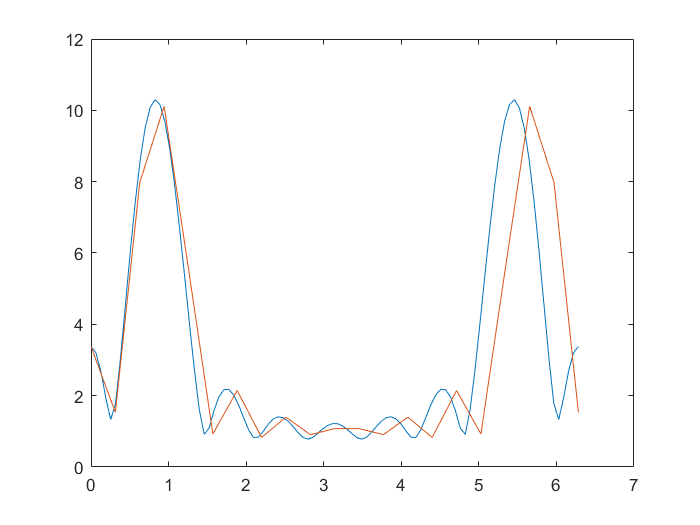

x=2.*cos(0.27*pi*n).*(escalon(n,0)-escalon(n,10));
w=linspace(0,2*pi,100);
X=DTFT(x,n,w);
Xf=fft(x);
N=20; %se escoge un valor cualquiera superior a 10, por el escalon
wk=(n.*2*pi)/N;
plot(w,abs(X),wk,abs(Xf)) %se compara la parte real

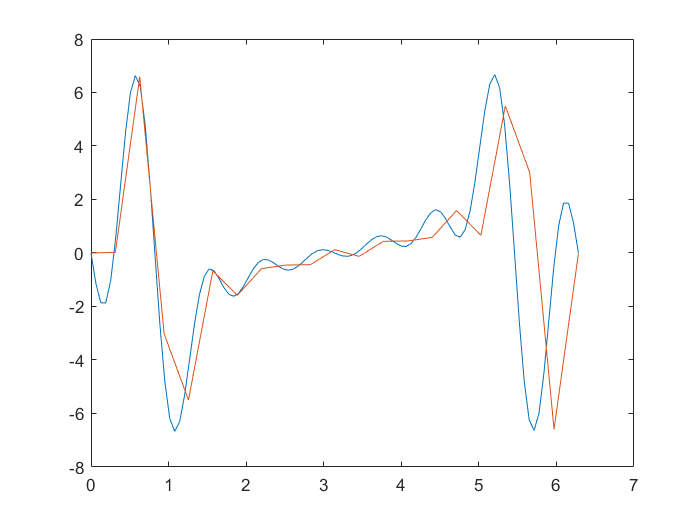

%la primera funcion se representa en azul y la segunda en rojo
plot(w,imag(X),wk,imag(Xf)) %y la parte imaginaria

5.11) Completad la DFT de una secuencia real de 8 puntos si X[k] = {0,25, 0,125  j0,3, 0, 0,125  j0,06, 0,5, ...}. Calculad la DFT de x1[n] = x[n]8, x2[n] = x[n + 5]8, x3[n] = x2[n], x4[n] = x[n]○8 x[n]8 y x5[n] = x[n]ej⇡n/4

X0=[0.25,0.125-1j*0.3,0,0.125-1j*0.06,0.5,]; %debo añadir los y tres numeros que me faltan
%partiendo de que 0.5 es el centro y a los lados estan los conjugados
X=[0.25,0.125-1j*0.3,0,0.125-1j*0.06,0.5,0.125+1j*0.06,0,0.125+1j*0.3,0.25]

X =    0.2500 + 0.0000i   0.1250 - 0.3000i   0.0000 + 0.0000i   0.1250 - 0.0600i   0.5000 + 0.0000i   0.1250 + 0.0600i   0.0000 + 0.0000i   0.1250 + 0.3000i   0.2500 + 0.0000i
